clear
%%%%%%%%%%%%%%%%%%%% Static Lift Drag %%%%%%%%%%%%%%%%%%%%%%
F = [
        0,-9.35984,0;
        18.7925,-11.5577,0;
        52.6455,-9.98958,0;
        162.344,6.27302,-0;
        239.411,24.7655,0;
        222.803,24.3547,0;
        209.479,-12.2005,0;
        206.028,-10.4411,0;
        212.269,-5.4064,0;
        204.517,18.0734,0;
        89.1192,40.3738,0;
        34.0222,36.6263,0;
        2.78943,34.6794,0;
        0,32.6788,0;
    ];
v = 35;
A = 0.070686;
% Drag, Lift
C = zeros(length(F), 2);

alpha = deg2rad([0 10 20 40 60 80 90 100 110 130 150 160 170 180]);
alpha_fine = 0:0.01:pi;
for i = 1:length(F)
    N_drag = [sin(alpha(i)) -cos(alpha(i)) 0];
    N_lift = [cos(alpha(i)) sin(alpha(i)) 0];
    F_drag = dot(F(i,:), N_drag);
    F_lift = dot(F(i,:), N_lift);
    C(i,1) =  (2/(v*v*A))*F_drag;
    C(i,2) =  (2/(v*v*A))*F_lift;
end

fit_drag = fit(alpha',C(:,1),'cubicinterp')

fit_drag =      Piecewise cubic interpolant:
       fit_drag(x) = piecewise polynomial computed from p
     Coefficients:
       p = coefficient structure

fit_lift = fit(alpha',C(:,2),'cubicinterp')

fit_lift =      Piecewise cubic interpolant:
       fit_lift(x) = piecewise polynomial computed from p
     Coefficients:
       p = coefficient structure

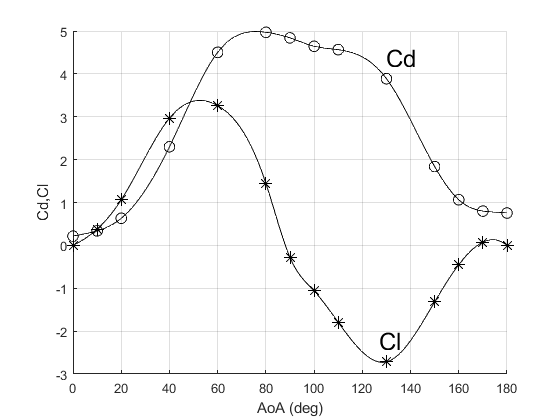


%Plot Cd, Cl
lables = ["Cd","Cl"];
coord_x = [rad2deg(alpha(end-4)), rad2deg(alpha(end-4))-3];
coord_y = [C(end-4,1)+0.5,C(end-4,2)+0.5];
blackPlot(rad2deg(alpha), C, rad2deg(alpha_fine),[fit_drag(alpha_fine),fit_lift(alpha_fine)],lables,18,coord_x,coord_y,'AoA (deg)','Cd,Cl','o*',8)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%% Static Rotation %%%%%%%%%%%%%%%%%
% tau = -1*[0, -4.85525, -4.88145, 4.78968, 4.458, 6.79218, 38.1482;
%         0, -6.7345, -10.1424, -11.4298, -19.4323, -15.3994, 17.3097;
%         0, -8.61375, -15.4033, -27.6492, -43.3226, -37.591, -3.52885;
%         0, -10.493, -20.6643, -43.868, -67.2129, -59.7875, -24.367;
%         0, -12.3722, -25.9252, -60.0882, -91.1031, -81.9743, -45.2059;
%         0, -14.2515, -31.1862, -76.3076, -114.993, -104.166, -66.0444
%       ];
tau = [ 0, 7.6742, 12.7729, 19.5395, 31.3774, 26.4952, -6.894, -21.6595, -38.2113, -35.362, -17.3416, -14.7248, -10.2292, 0;
        0, 9.5534, 18.0338, 35.759, 55.2677, 48.6868, 13.9481, -1.05669, -16.9844, -14.9103, -8.42965, -11.3225, -9.9503, 0;
        0, 11.4326, 23.2948, 51.9785, 79.158, 70.8785, 34.7866, 19.5461, 4.2424, 5.54138, 0.4823, -7.92031, -9.67132, 0;
        0, 13.3119, 28.5557, 68.1979, 103.048, 93.0701, 55.6251, 40.1489, 25.4693, 25.9931,9.3942, -4.5181, -9.3945, 0;
      ];

Ct = (2/(v*v*A))*tau;
% cm = (0.9:-0.1:0.4)
cm = 0.75:-0.1:0.45;

[xData, yData, zData] = prepareSurfaceData(alpha, cm, Ct );

fitT = fit( [xData, yData], zData, 'biharmonicinterp')

     Biharmonic spline interpolant:
       fitT(x,y) = biharmonic surface computed from p
     Coefficients:
       p = coefficient structure



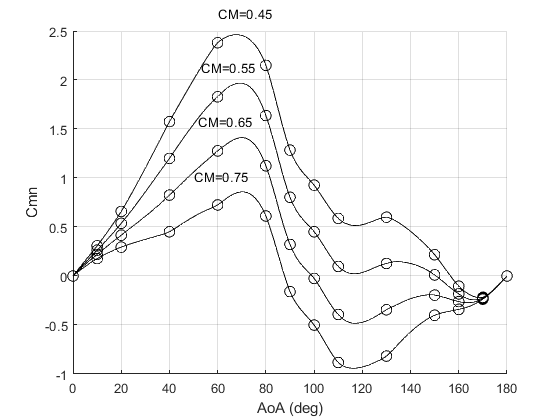


pos = 5;
lables = ["CM=0.75","CM=0.65","CM=0.55","CM=0.45"];
coord_x = [rad2deg(alpha(pos))-10,rad2deg(alpha(pos))-8,rad2deg(alpha(pos))-7,rad2deg(alpha(pos)),rad2deg(alpha(pos))];
coord_y = [fitT(alpha(pos),0.75)+0.3,fitT(alpha(pos),0.65)+0.3,fitT(alpha(pos),0.55)+0.3,fitT(alpha(pos),0.45)+0.3];
blackPlot(rad2deg(alpha), Ct', rad2deg(alpha_fine),[fitT(alpha_fine,0.75)',fitT(alpha_fine,0.65)', fitT(alpha_fine,0.55)', fitT(alpha_fine,0.45)'],lables,10,coord_x,coord_y,'AoA (deg)','Cmn','o', 8)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%% Dynamic Rotation %%%%%%%%%%%%%%%%%%%%%
%tau = -0.04;
tau = -0.04607;
F = [0.4253, -0.01333, 0];
% Rotation rate (rad/s)
w = 1.0472

w = 1.0472

Ct_rot = (2/(w*w*A))*tau

Ct_rot = -1.1887


C_rot = zeros(length(alpha),2);
for i = 1:length(alpha)
    N_drag = [-sin(alpha(i)) -cos(alpha(i)) 0];
    N_lift = [-cos(alpha(i)) sin(alpha(i)) 0];
    F_drag = dot(F, N_drag);
    F_lift = dot(F, N_lift);
    C_rot(i,1) =  (2/(w*w*A))*F_drag;
    C_rot(i,2) =  (2/(w*w*A))*F_lift;
end

fit_drag_rot = fit(alpha',C_rot(:,1),'poly2')

fit_drag_rot =      Linear model Poly2:
     fit_drag_rot(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       4.496  (4.322, 4.67)
       p2 =      -14.36  (-14.93, -13.8)
       p3 =      0.7236  (0.3414, 1.106)

fit_lift_rot = fit(alpha',C_rot(:,2),'poly3')

fit_lift_rot =      Linear model Poly3:
     fit_lift_rot(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients (with 95% confidence bounds):
       p1 =      -1.561  (-1.602, -1.52)
       p2 =       7.495  (7.301, 7.689)
       p3 =      -1.183  (-1.431, -0.9345)
       p4 =      -10.92  (-11, -10.84)

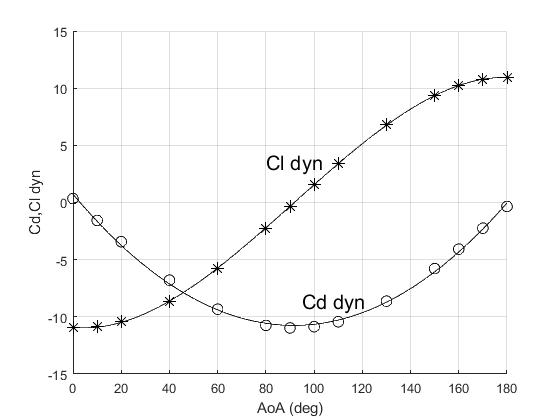


pos = 8;
lables = ["Cd dyn","Cl dyn"];
coord_x = [rad2deg(alpha(pos))-5,rad2deg(alpha(pos))-20];
coord_y = [fit_drag_rot(alpha(pos))+2,fit_lift_rot(alpha(pos))+2];
blackPlot(rad2deg(alpha), C_rot, rad2deg(alpha_fine),[fit_drag_rot(alpha_fine),fit_lift_rot(alpha_fine)],lables,15,coord_x,coord_y,'AoA (deg)','Cd,Cl dyn','o*', 8)